## Assignment 3 - Battery modelling case

PART 1


clear;
ProdConData = readtable('data.csv'); % solar prod, consumption
PV = zeros(1, 8762);
Pcons = zeros(1, 8762);


H=size(ProdConData);

for i = 1 : H
    PV(i) =ProdConData{i,1};  % array with PV production
    Pcons(i) = ProdConData{i,2}; % array with consumption
end

Pnom =  10;  % nominal power in kW
BatteryCap = 0; % Battery capacity kWh
BatteryMinCap=0;
BatteryMaxCap=120;

Pmax = 1.5*Pnom;

rounds=25;
IncreaseInCap=BatteryMaxCap/(rounds-1);



for j = 1 : rounds
    
    BatteryCap = (j-1)*IncreaseInCap;
    if BatteryCap == 0
        BatteryCap = 0.00001;
    end
    
    SOC = 0; % battery state of charge
    Pchar = 0; % counter for how much is charged
    Pdischar = 0; % counter for how much is discharged
    charge_counter = 0 ;
    discharge_counter = 0 ;
    Pbuy=0;
    Psell=0;
    
    for i = 1:length(PV)
        
        Pbat= Pcons(i)-PV(i);
        
        if Pbat<0 %we are charging the battery
            if abs(Pbat)>Pmax
                Pbat = -Pmax;           
            end
            
            Eff_1way = 1-0.1*Pbat/Pnom;
            
            if abs(Pbat)>(1-SOC)*BatteryCap      % if the actual capacity is higher than the batery capacity  the power is adjusted
                Pbat = -(1-SOC)*BatteryCap ;
               
            end
            
            if abs(Pbat)==(1-SOC)*BatteryCap %we calculate the number of times the battery is fully charged
                charge_counter = charge_counter +1 ; % we obtain the number of times that the battery is fully charged
            end
            
            SOC = SOC-Pbat/(Eff_1way*BatteryCap);% we calculate the new state of charge value
            Pchar=Pbat+Pchar;    % set up for the counter that will count the  total charge during year
            
        end
        
        if Pbat>0 %we are discharging the battery
            
            if abs(Pbat)>Pmax
                Pbat = Pmax;
            end
            
            Eff_1way = 1-0.1*abs(Pbat)/Pnom;
            
            if abs(Pbat)>SOC*BatteryCap*Eff_1way      % if the actual capacity is higher than the batery capacity  the power is adjusted
                Pbat = (SOC)*BatteryCap*Eff_1way;
            end
            
            if abs(Pbat) == SOC*BatteryCap*Eff_1way
                discharge_counter = discharge_counter +1;  % we obtain the number of times that the battery is fully discharged
            end
            
            SOC = SOC-Pbat/(Eff_1way*BatteryCap);% we calculate the new state of charge value
            Pdischar=Pbat+Pdischar;    % set up for the counter that will count the  total discharge during year
            
        end
       
      
        Pbat_time(i)= Pbat;
        SOC_time(i) = SOC ;
        
       
    end   %i loop

   
    CapCounter(j)= BatteryCap; %counter for the battery's capacity Part 2
    yearly_discharge(j)= Pdischar; % counter for the yearly discharge capacity Part 2
   
    TotalDischarge(j)=sum(yearly_discharge(j));
    
    

    if BatteryCap==50
    yearly_discharge(j)=Pdischar;
    yearly_discharge_BattCap50(j)=yearly_discharge(j);
    
    timesofdischargeBattCap50=discharge_counter;
    timesofchargeBattCap50=charge_counter;
    end

    
    BatteryCost=Pnom*929+BatteryCap*331;
    LCOS=BatteryCost/Pdischar
    values_LCOS(j)=LCOS;
   
   
end           %j loop

LCOS = 2.9578e+06

LCOS = 7.7014

LCOS = 4.6564

LCOS = 3.6562

LCOS = 3.1502

LCOS = 2.8425

LCOS = 2.6378

LCOS = 2.4908

LCOS = 2.3923

LCOS = 2.3595

LCOS = 2.3596

LCOS = 2.3849

LCOS = 2.4340

LCOS = 2.4993

LCOS = 2.5757

LCOS = 2.6605

LCOS = 2.7509

LCOS = 2.8462

LCOS = 2.9476

LCOS = 3.0530

LCOS = 3.1596

LCOS = 3.2679

LCOS = 3.3780

LCOS = 3.4900

LCOS = 3.6019



sprintf("Total discharged capacity for BattCap=50 ")
sum(yearly_discharge_BattCap50)
sprintf("Number of full discharges")
timesofdischargeBattCap50
sprintf("Number of full charges")
timesofchargeBattCap50


figure(1);
plot (SOC_time,'.');
xlabel('Time (Hours)')
ylabel('SOC')

figure(2);
plot(Pbat_time,'.');
xlabel('Time (Hours)')
ylabel('Pbat (kWh)')





values_LCOS = 	1.0e+06 *

    2.9578    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


ERROR: empty array (i don't know why)


ans = "Total discharged capacity for BattCap=50 "

ans = 1.0951e+04

ans = "Number of full discharges"

timesofdischargeBattCap50 = 3834

ans = "Number of full charges"

timesofchargeBattCap50 = 1472

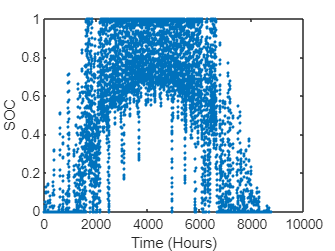

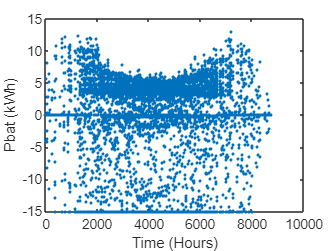

values_LCOS 
disp("NOTE OF ERROR: empty array (i don't know why). As showed above, the LCOS values are calculated, but not stored" )







**Random 5-day interval**


x1=unidrnd(8760,1,1)

x1 = 7935

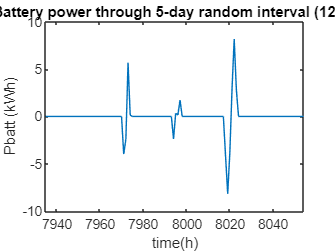

if x1<(8760-120)
    x2=x1+119;
else
    x1=unidrnd(n)
end
dayinterval=x1:x2;
    
%Y_Pbatt: vector that stores 120h-interval Pbatts
interval_Pbatt=zeros(1,120);
interval_SOC=zeros(1,120);
j=0;
for i= 1:120
    j=j+1;
    interval_Pbatt(j)=Pbat_time(i);
    interval_SOC(j)=SOC_time(i);
end

plotPbatt_daily=plot(dayinterval,interval_Pbatt);
title("Battery power through 5-day random interval (120h)");
xlabel("time(h)");
ylabel("Pbatt (kWh)");

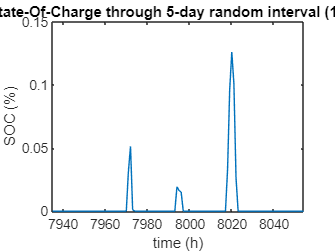


plotSOC_daily=plot(dayinterval,interval_SOC);
title("State-Of-Charge through 5-day random interval (120h)");
xlabel("time (h)");
ylabel("SOC (%)");

PART 2 - Yearly discharge

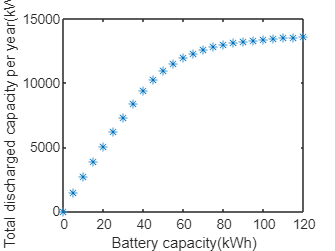


figure(3);
plot(CapCounter,yearly_discharge,'*');
xlabel('Battery capacity(kWh)')
ylabel('Total discharged capacity per year(kWh)')

PART3

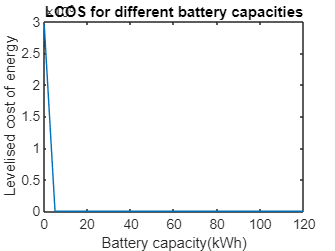



values_LCOS 
disp("NOTE OF ERROR: empty array (i don't know why). As showed above, the LCOS values are calculated, but not stored" )



figure(4)
plot(CapCounter,values_LCOS,'-')
title("LCOS for different battery capacities")
xlabel('Battery capacity(kWh)')
ylabel('Levelised cost of energy')